# Uso de nube de puntos

Construya usted alguna secuencia deoperaciones que le permita resolver el problema

clear all
% Configuración inicial del robot
rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Shutting down global node /matlab_global_node_31637 with NodeURI http://PCIrandi:36411/ and MasterURI http://172.17.0.1:11311.
Initializing global node /matlab_global_node_28393 with NodeURI http://PCIrandi:37393/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates  


q = zeros(6,1);

Buscamos objetos desconocidos con posición y orientación indefinidos. Las latas y botella, se encuentran por ejemplo en:

Nos movemos a región donde piezas, posiciones y orientaciones son desconocidas; por ejemplo $\left(x,y,z\right)=\left(0\ldotp 621,0,0\ldotp 5\right)$ con una rotaciòn del gripper de $-\frac{\pi }{2}$

%% Buscamos la posición de algunos objetos y botes de disposición final de forma manual
gripperX = 0.6335;
gripperY = 0.042;
gripperZ = 0.5;


gripperTheta = -1.57;


q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);

## Comparamos las imagenes RGB y de profundidad.

El empalme es ideal **solo** en el simulador.

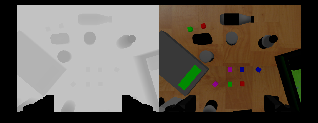

rgbImg = rosReadImage(rgbImgSub.LatestMessage);

depthImg = rosReadImage(rgbDptSub.LatestMessage); 

montage({depthImg,rgbImg})

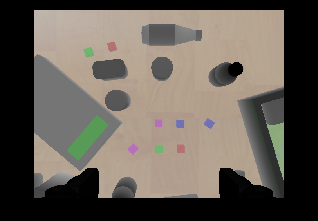


C = imfuse(rgbImg,depthImg,"blend");
imshow(C)
hold off

Prompt en ChatGPT: *Coloca una linea vertical y horizontal a la mitad de una foto en matlab*

hold on;

% Obtener dimensiones
[alto, ancho, ~] = size(C);

% Coordenadas del centro
x_centro = ancho / 2;
y_centro = alto / 2;

% Dibujar línea vertical en el centro
line([x_centro x_centro], [1 alto], 'Color', 'r', 'LineWidth', 2);

% Dibujar línea horizontal en el centro
line([1 ancho], [y_centro y_centro], 'Color', 'r', 'LineWidth', 2);


% hold off;
% impixelinfo

Prompt en ChatGPT: Dibuja un punto en el punto (320,300)

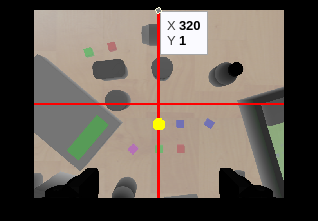

% Coordenadas del punto
x = 320;
y = 240+60/(0.0125*(gripperZ*100-40)+1);

% Dibujar punto rojo en (320, 300)
plot(x, y, 'yo', 'MarkerSize', 8, 'LineWidth', 2 , 'MarkerFaceColor','y');  % 'ro' = rojo con círculo

hold off;

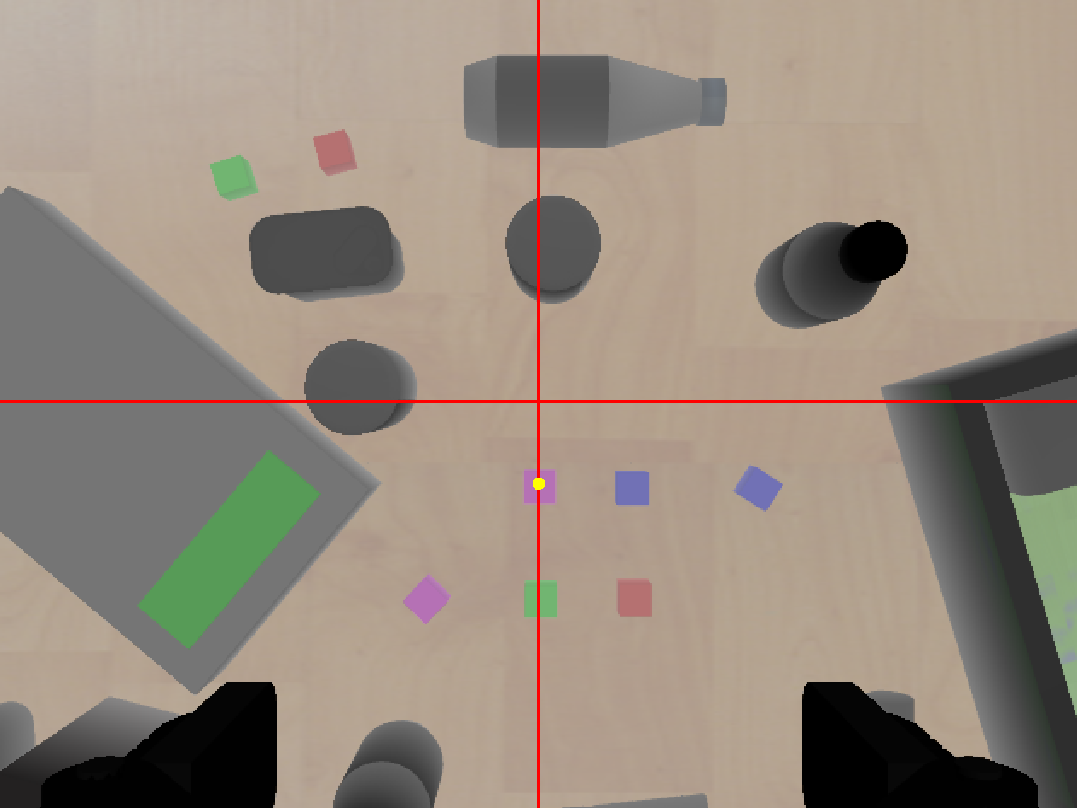

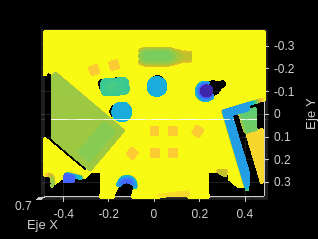

figure
focalLength      = [561,561];

principalPoint   = [320, 240];
imageSize        = size(depthImg);
intrinsics       = cameraIntrinsics(focalLength,principalPoint,imageSize);

depthScaleFactor = 0.9;
maxCameraDepth   = 1;

NubePuntos = pcfromdepth(depthImg,depthScaleFactor, intrinsics,DepthRange=[0 maxCameraDepth]);
% 
% % pcshow(NubePuntos)
pcshow(NubePuntos, VerticalAxis="Y", VerticalAxisDir="Down", ViewPlane="YX",MarkerSize=50)
xlabel('Eje X')
ylabel('Eje Y')

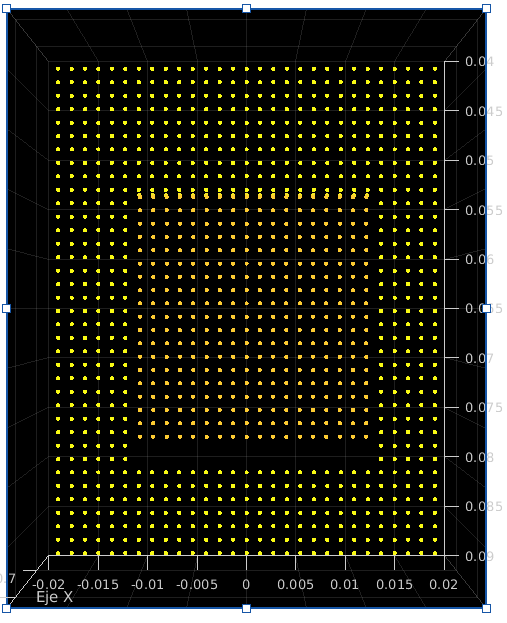  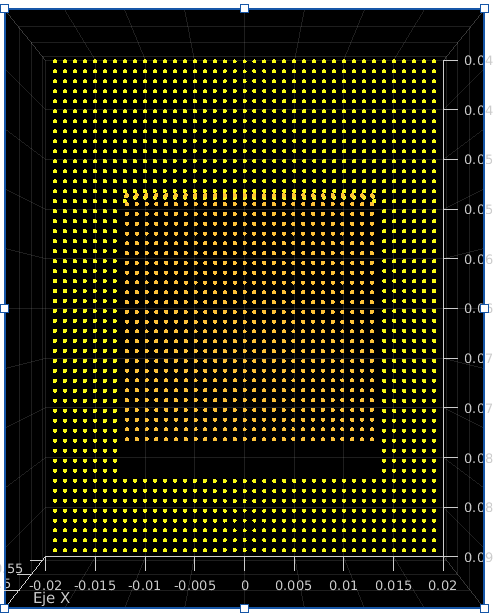

Fig. Nuves de puntos a distintas alturas.

## Transformaciones del marco de referencia de la cámara al marco de referencia del robot


NubePuntos = pcfromdepth(depthImg,depthScaleFactor, intrinsics,DepthRange=[0 maxCameraDepth]);
% 
% % pcshow(NubePuntos)
fprintf("Mostramos la nube de puntos original:")

Mostramos la nube de puntos original:

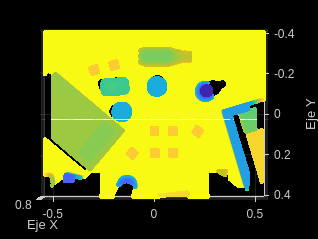

pcshow(NubePuntos, VerticalAxis="Y", VerticalAxisDir="Down", ViewPlane="YX",MarkerSize=50)
xlabel('Eje X')
ylabel('Eje Y')


%Transformación homogénea de la cámara al gripper
TCameraGripper = [1 0 0  0.00;...
                  0 1 0  -0.06;...
                  0 0 1  -0.1819
                  0 0 0  1.00];

%Transformación homogénea del gripper a la base del robot
gripperTranslation = [gripperX;gripperY;gripperZ];

gripperRotation = [cos(gripperTheta),sin(gripperTheta),0;
                       sin(gripperTheta),-cos(gripperTheta),0;
                       0,0,-1];
TGripperRobot = [gripperRotation,gripperTranslation;
            0,0,0,1];

tform = affinetform3d(TGripperRobot*TCameraGripper);

figure
fprintf("Mostramos la nube de puntos transformada:")

Mostramos la nube de puntos transformada:

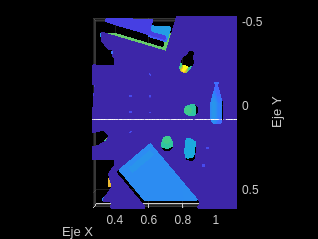

NubePuntos_Robot = pctransform(NubePuntos,tform);
pcshow(NubePuntos_Robot, VerticalAxis="Y", VerticalAxisDir="Down", ViewPlane="YX",MarkerSize=50)
xlabel('Eje X')
ylabel('Eje Y')

## Generando una mascara para estudiar una pieza individual

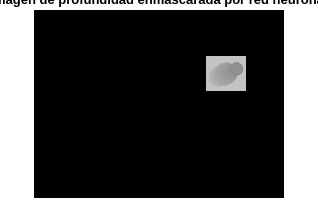

% Obtener tamaño de la imagen
[rows, cols] = size(depthImg);  % Puede ser de tipo double, uint16, etc.

% Inicializar máscara binaria
mask = NaN(rows, cols);  % máscara de ceros (lógica)

x = 442;
y = 119;
w = 100;
h = 90;


% Definir los límites del rectángulo
x_start = x;
x_end = min(x + w - 1, cols);
y_start = y;
y_end = min(y + h - 1, rows);

% Asignar 1s (true) en la región de interés
mask(y_start:y_end, x_start:x_end) = 1;

profundidadEnmascarada = mask.*depthImg;

% Visualizar la máscara y la imagen
figure;
imshow(profundidadEnmascarada); title('Imagen de profundidad enmascarada por red neuronal');

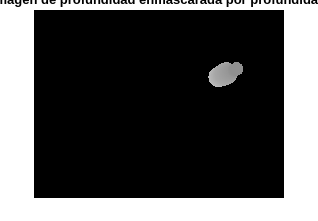


profundidadEnmascarada(profundidadEnmascarada>0.76) = NaN;
figure;
imshow(profundidadEnmascarada); title('Imagen de profundidad enmascarada por profundidad');

NubePuntosEnmascarada = pcfromdepth(profundidadEnmascarada,depthScaleFactor, intrinsics,DepthRange=[0 maxCameraDepth]);


NubePuntos_Robot = pctransform(NubePuntosEnmascarada,tform);
NubePuntos_RobotOptimizada = removeInvalidPoints(NubePuntos_Robot)

NubePuntos_RobotOptimizada =   pointCloud with properties:

     Location: [4046×3 single]
        Count: 4046
      XLimits: [0.7561 0.8297]
      YLimits: [-0.2089 -0.1432]
      ZLimits: [-0.1384 0.0537]
        Color: []
       Normal: []
    Intensity: []


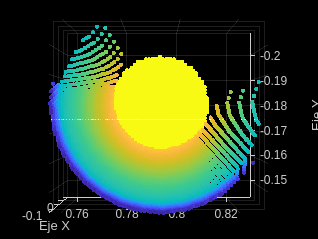

pcshow(NubePuntos_RobotOptimizada, VerticalAxis="Y", VerticalAxisDir="Down", ViewPlane="YX",MarkerSize=50)
xlabel('Eje X')
ylabel('Eje Y')

model = pcfitcuboid(NubePuntos_RobotOptimizada)

model =   cuboidModel with properties:

     Parameters: [0.7904 -0.1723 -0.0424 0.0738 0.0570 0.1922 0 0 20.0000]
         Center: [0.7904 -0.1723 -0.0424]
     Dimensions: [0.0738 0.0570 0.1922]
    Orientation: [0 0 20.0000]


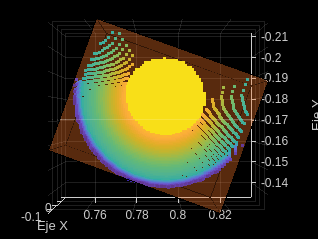

plot(model)

%% Buscamos la posición de algunos objetos y botes de disposición final de forma manual
gripperX = model.Center(1);
gripperY = model.Center(2);
gripperZ = model.Center(3)+model.Dimensions(3)/2;%model.Dimensions(3)/2+model.Center(3);


gripperTheta = -1.57;%model.Orientation(3)*pi/180;


q = MoverRobotXYZ(gripperX,gripperY,gripperZ,gripperTheta,q,trajAct,trajGoal,jointSub);